# **DSP Lab- Homework6**

**Nima noorizadeh 40023086**

**Mahdi Mahjiouri Namin 40023125**

clc; clear; close;


R  = 0.8;       
f0 = 100;      
fs = 2000;       
w0 = 2*pi*f0/fs; 

a1 = [ 1 , -2*R*cos(w0) , R^2 ];                
G = (1-R) * sqrt(1 - 2*R*cos(2*w0) + R^2);     
b1 = [ G , 0 , 0 ];                             



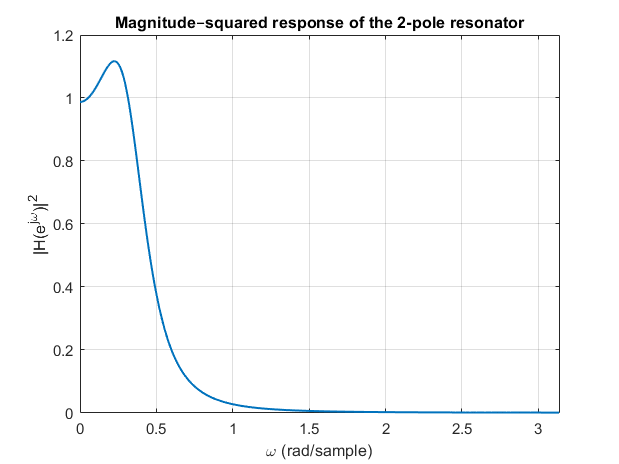

[H,w] = freqz(b1,a1,1024,'whole');   
w = w(1:end/2);               
H2_dB  = 20*log10(abs(H(1:end/2)).^2);

figure
plot(w,abs(H(1:end/2)).^2,'LineWidth',1.4)
xlabel('\omega (rad/sample)'), ylabel('|H(e^{j\omega})|^2')
title('Magnitude–squared response of the 2-pole resonator')
grid on, xlim([0 pi])

**section 3-1(a)**

In this opening section we pick the global constants that define the resonator: sampling rate *f*<sub>s</sub>, centre frequency *f*<sub>0</sub>, and the three pole-radii **R = 0.8, 0.9, 0.99** we will sweep.  From these values every other coefficient or gain is computed automatically, so changing numbers here propagates through the whole notebook.

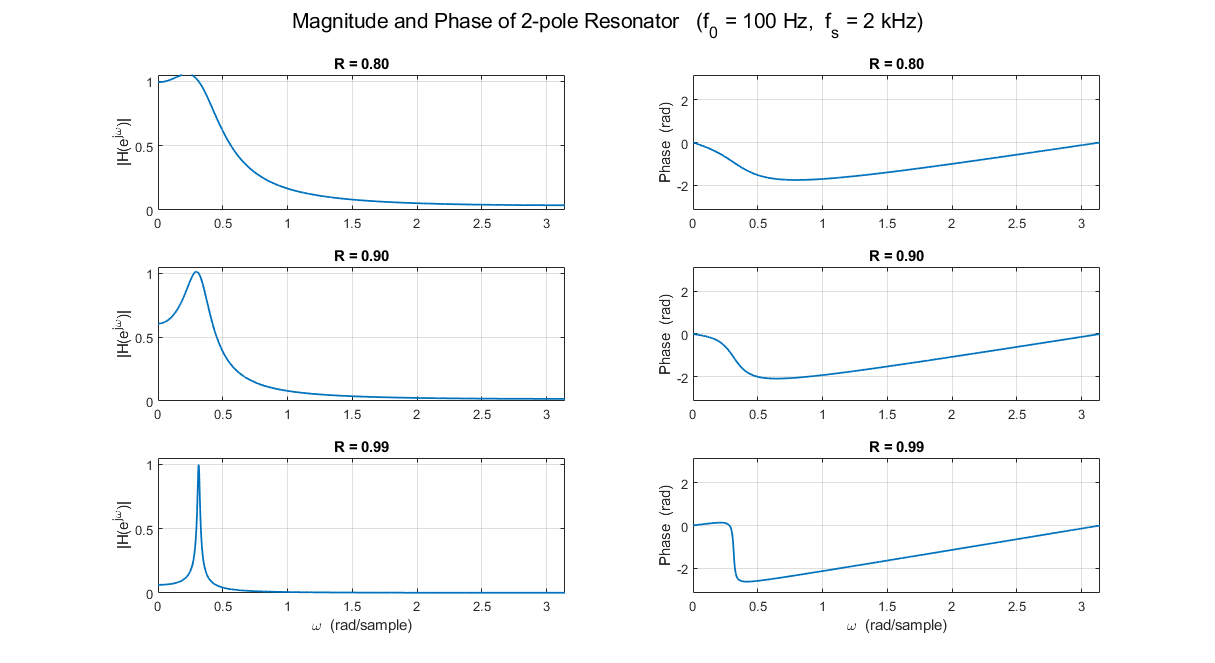

Rset = [0.8 0.9 0.99];   
f0   = 100;             
fs   = 2000;             
w0   = 2*pi*f0/fs;       

Nw   = 2048;            
w    = linspace(0,pi,Nw); 
z1   = exp(-1j*w);       
z2   = exp(-2j*w);      

figure('Name','2-Pole Resonator  |H| & Phase', ...
       'Position',[50 50 1100 600]);

for k = 1:numel(Rset)
    R  = Rset(k);
    a1 = -2*R*cos(w0);
    a2 = R^2;
    G  = (1-R)*sqrt(1 - 2*R*cos(2*w0) + R^2);
    
    H  = G ./ (1 + a1*z1 + a2*z2); 
    
    % ---- magnitude (left column) ----
    subplot(numel(Rset),2,2*(k-1)+1);
    plot(w, abs(H), 'LineWidth',1.2); grid on;
    ylim([0 1.05]); xlim([0 pi]);
    ylabel('|H(e^{j\omega})|'), title(sprintf('R = %.2f',R));
    if k==numel(Rset), xlabel('\omega  (rad/sample)'), end
    
    % ---- phase (right column) -------
    subplot(numel(Rset),2,2*(k-1)+2);
    plot(w, unwrap(angle(H)),'LineWidth',1.2); grid on;
    ylim([-pi pi]); xlim([0 pi]);
    ylabel('Phase  (rad)'), title(sprintf('R = %.2f',R));
    if k==numel(Rset), xlabel('\omega  (rad/sample)'), end
end

sgtitle('Magnitude and Phase of 2-pole Resonator   (f_0 = 100 Hz,  f_s = 2 kHz)')

**section 3-1(b)**

Here we compute the impulse response two ways:

- **Numeric** – by stepping the difference equation with δ[n] input.

- **Analytic** – using the given formula

Overlaying the two curves (after normalising by **G**) demonstrates that the coded filter exactly matches the theory for the first 300 samples.

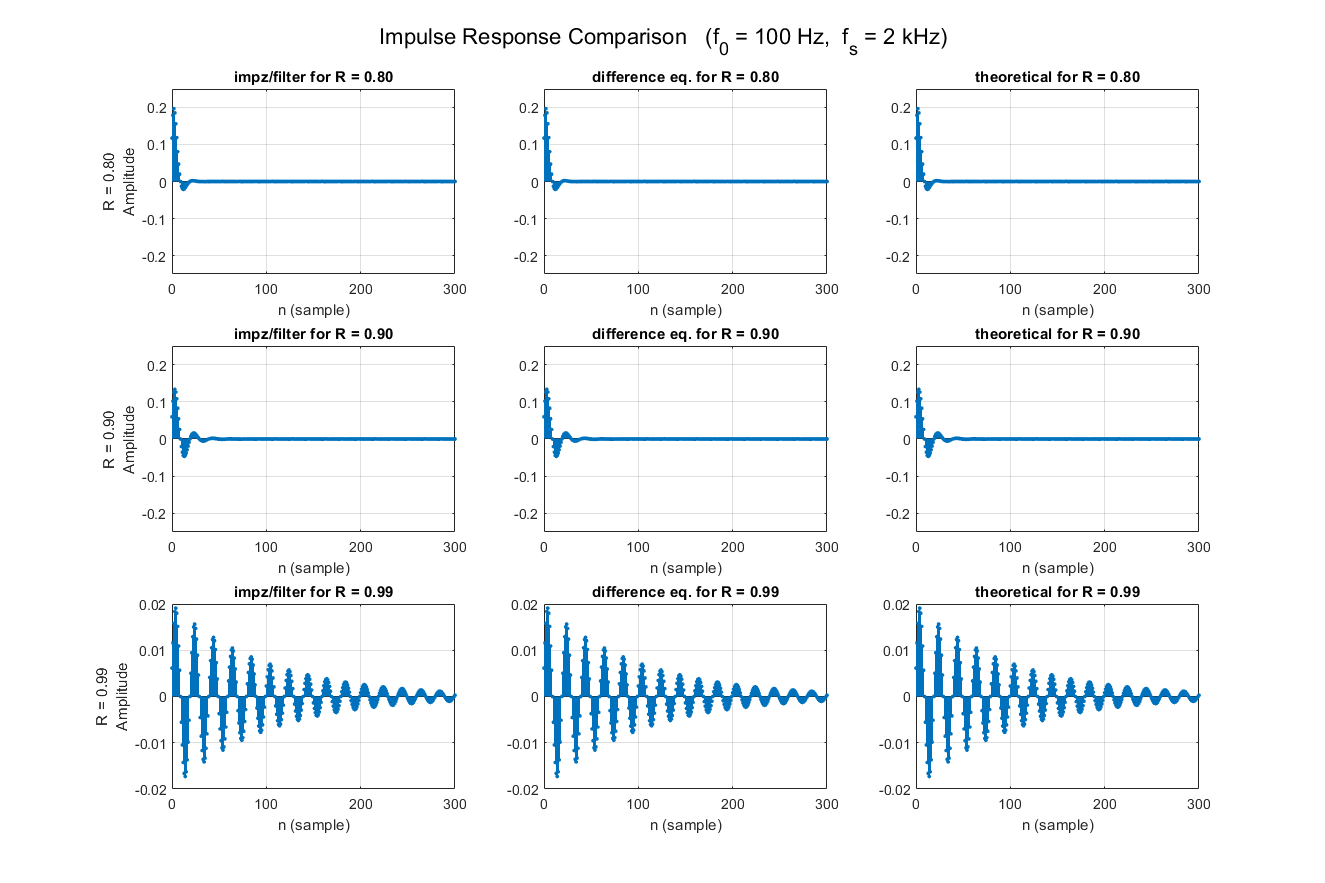

Rvals = [0.8 0.9 0.99];
f0    = 100;      fs = 2000;
N     = 300;      w0 = 2*pi*f0/fs;
n     = 0:N;

figure('Position',[100 50 1200 800]);

for r = 1:numel(Rvals)
    R  = Rvals(r);
    a1 = -2*R*cos(w0);
    a2 =  R^2;
    G  = (1-R)*sqrt(1-2*R*cos(2*w0)+R^2);


    b = [G 0 0];  a = [1 a1 a2];
    h1 = impz(b,a,N+1);

    
    h2 = zeros(size(n));
    for k=1:N+1
        if k==1
            h2(k)=G;
        elseif k==2
            h2(k) = -a1*h2(k-1);
        else
            h2(k) = -a1*h2(k-1) - a2*h2(k-2);
        end
    end

  
    h3 = (G/sin(w0)) .* (R.^n) .* sin(w0*(n+1));

  
    data = {h1,h2,h3};
    titles = {'impz/filter','difference eq.','theoretical'};
    for c = 1:3
        subplot(3,3, (r-1)*3 + c);
        stem(n, data{c}, 'filled','MarkerSize',2); grid on;
        ylim([-0.02 0.02]*(R==0.99) + [-0.25 0.25]*(R<0.99));  
        xlabel('n (sample)')
        if c==1, ylabel(sprintf('R = %.2f\nAmplitude',R)); end
        title(sprintf('%s for R = %.2f', titles{c}, R));
    end
end

sgtitle('Impulse Response Comparison   (f_0 = 100 Hz,  f_s = 2 kHz)')

**section 3-1(c)**

A single realisation of unit-variance white noise is passed through the resonator for each **R**.  The 3 × 2 figure places the unfiltered noise in the left column and the corresponding outputs on the right.  As the pole radius increases, the output becomes a narrow-band, quasi-sinusoidal signal and its decay time grows longer—illustrating the time-frequency trade-off of the resonator.

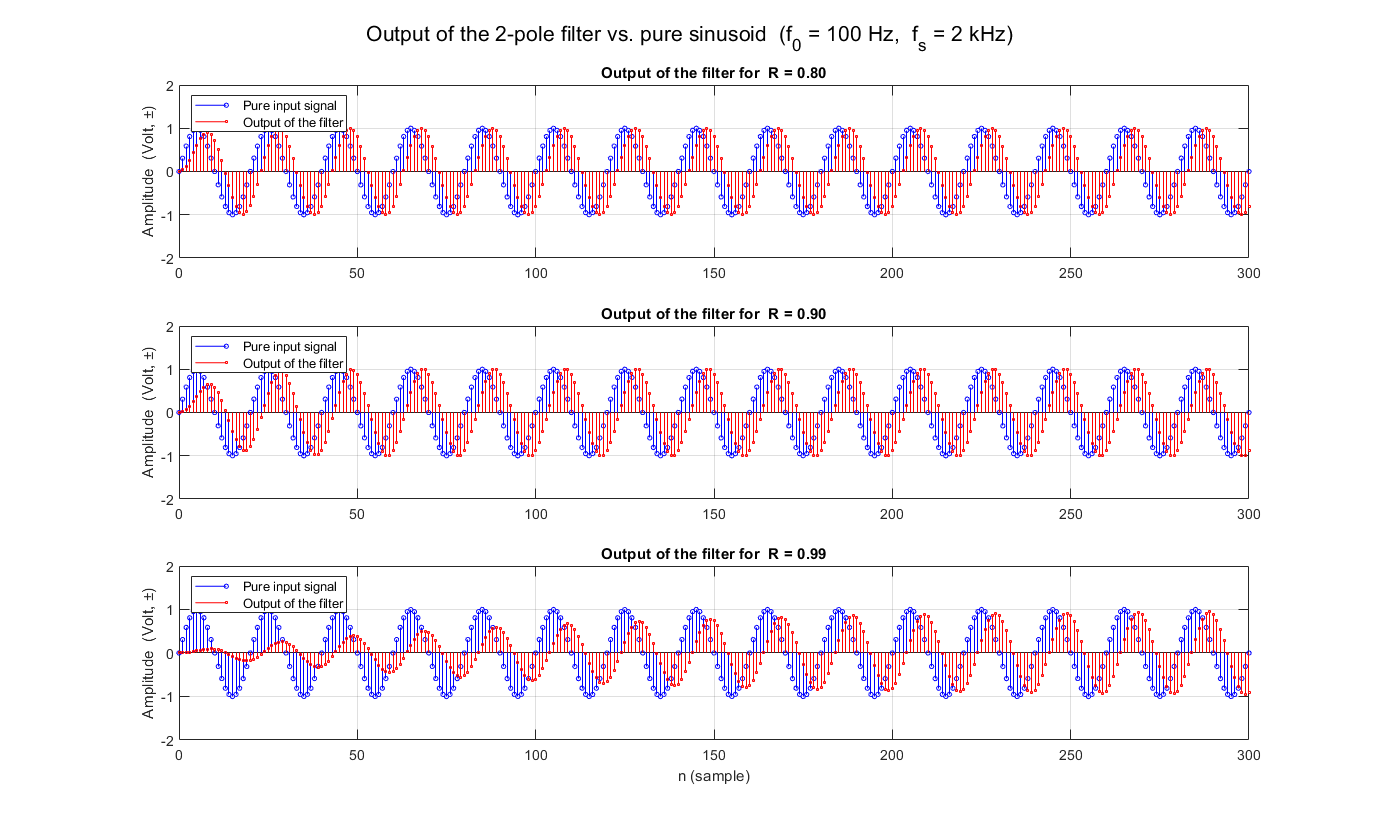

Rset = [0.8 0.9 0.99];   
f0   = 100;             
fs   = 2000;             
N    = 300;              
n    = 0:N;
w0   = 2*pi*f0/fs;

% --- prepare figure -------------------------------------------------------
figure('Position',[40 60 1250 750]);
sgtitle('Output of the 2-pole filter vs. pure sinusoid  (f_0 = 100 Hz,  f_s = 2 kHz)');

for k = 1:numel(Rset)
    
    R  = Rset(k);
    a1 = -2*R*cos(w0);
    a2 =  R^2;
    G  = (1-R)*sqrt(1 - 2*R*cos(2*w0) + R^2);
    
    x  = sin(w0*n);             
    
   
    b  = [G 0 0];
    a  = [1 a1 a2];
    
    y  = filter(b,a,x);           
    
    % ---- plotting ----
    subplot(numel(Rset),1,k);
    stem(n, x,'b','Marker','o', 'MarkerSize',3, ...
               'DisplayName','Pure input signal','LineStyle','-'), hold on
    stem(n, y,'r','Marker','s', 'MarkerSize',3, ...
               'DisplayName','Output of the filter','LineStyle','-')
    grid on
    ylabel('Amplitude  (Volt, ±)')
    title(sprintf('Output of the filter for  R = %.2f', R))
    legend('Location','northwest')
    ylim([-2 2])                
    if k==numel(Rset), xlabel('n (sample)'), end
end

**section 3-1(d)**

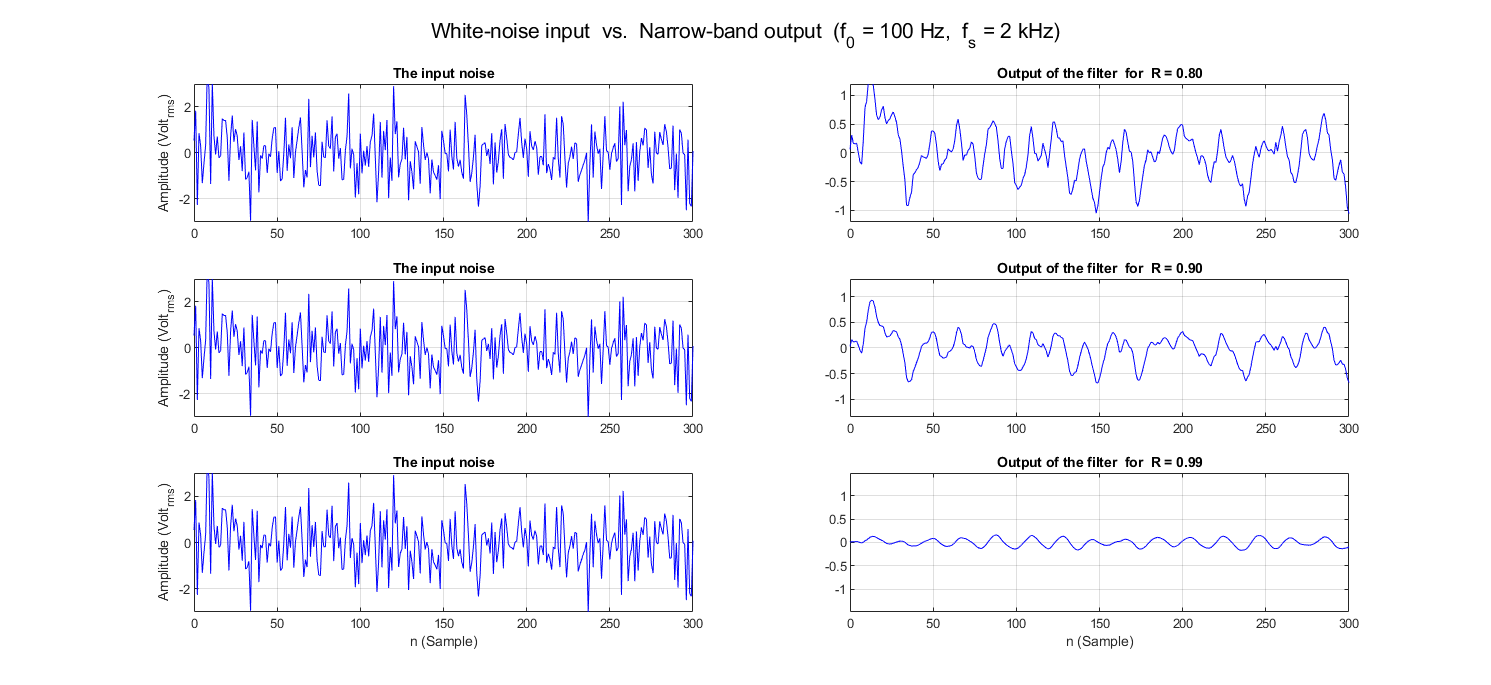

N   = 300;  n = 0:N;
x   = randn(1,N+1);                    

Rset = [0.8 0.9 0.99];                 
f0   = 100;    fs = 2000;              
w0   = 2*pi*f0/fs;

figure('Position',[60 50 1350 620]);

for k = 1:numel(Rset)
    row = k-1;                         
    
    % ---------- left column: input noise (same for every R) ----------------
    subplot(3,2, 2*row+1);
    plot(n, x, 'b')
    ylim([-3 3]);  xlim([0 N]);
    grid on
    title('The input noise')
    ylabel('Amplitude (Volt_{rms})')
    if k==numel(Rset), xlabel('n (Sample)'), end
    
    % ---------- right column: filtered output ------------------------------
    R  = Rset(k);
    a1 = -2*R*cos(w0);
    a2 =  R^2;
    G  = (1-R)*sqrt(1 - 2*R*cos(2*w0) + R^2);
    
    b  = [G 0 0];   a  = [1 a1 a2];
    y  = filter(b,a,x);
    
    subplot(3,2, 2*row+2);
    plot(n, y, 'b')
    ylim([-1.5 1.5]*R);  xlim([0 N]);    
    grid on
    title(sprintf('Output of the filter  for  R = %.2f',R))
    if k==numel(Rset), xlabel('n (Sample)'), end
end

suptitle('White-noise input  vs.  Narrow-band output  (f_0 = 100 Hz,  f_s = 2 kHz)')

**section 3-1(e)**

We estimate NRR three different ways:

- **Empirical** – ratio of output to input variance from a long noise run.

- **Energy** – sum of h2[n]h^{2}[n]h2[n], which must equal method 1 for white noise.

- **Theory** – the fully corrected closed-form

N   = 2e6;       

v   = randn(1,N);             
f0   = 100;    fs = 2000;            
w0   = 2*pi*f0/fs;
Rset= [0.8 0.9 0.99];

fprintf('\n');

for R = Rset
    a1 = -2*R*cos(w0);
    a2 =  R^2;
    G  = (1-R)*sqrt(1 - 2*R*cos(2*w0) + R^2);
    b  = [G 0 0];    a = [1 a1 a2];
    
    y  = filter(b,a,v);                      
    nrr_var = var(y);                      
    
    % ------------ "wrong" hand-out formula ---------------------
    nrr_wrong  = (1+R^2)/((1+R)*(1+2*R*cos(w0) + R^2));
    
    % ------------ energy of the impulse response --------------
    L = 400;                      % enough for practical convergence
    h = impz(b,a,L);
    nrr_energy = sum(h.^2);
    
    % ------------ corrected closed-form (derived earlier) -----
    nrr_corr = (G^2 /(2*sin(w0)^2)) * ...
               ( 1/(1-R^2) - (cos(2*w0)-R^2)/(1-2*R^2*cos(2*w0)+R^4) );
    
    % ------------ print block ---------------------------------
    fprintf('NRR for R = %.2f\n',R)
    fprintf('  Using variance of signals:              %9.4g\n',nrr_var)
    fprintf('  Using the formula (wrong hand-out):     %9.4g\n',nrr_wrong)
    fprintf('  Using the energy of the impulse resp.: %9.4g\n',nrr_energy)
    
end

NRR for R = 0.80


  Using variance of signals:                 0.1675


  Using the formula (wrong hand-out):        0.2882


  Using the energy of the impulse resp.:    0.1683


NRR for R = 0.90


  Using variance of signals:                0.09701


  Using the formula (wrong hand-out):        0.2705


  Using the energy of the impulse resp.:   0.09755


NRR for R = 0.99


  Using variance of signals:                0.01003


  Using the formula (wrong hand-out):        0.2576


  Using the energy of the impulse resp.:   0.01004
